# Modelowanie i symulacja w programie MATLAB cz.2

## Jan Rosa 410269 AiR

## Zad 1

### Zad a

 Utwórz m-skrypt wczytujący dane z pliku daneP.csv a następnie realizującego wizualizację danych na wykresie typu plot (każda zmienna na osobnym wykresie). Dodaj do każdego wykresu osobny tytuł. - Wskazówka: użyj import wizarda do importu danych, następnie wygeneruj m-funkcję do importu danych i wykorzystaj ją w swoim m-skrypcie

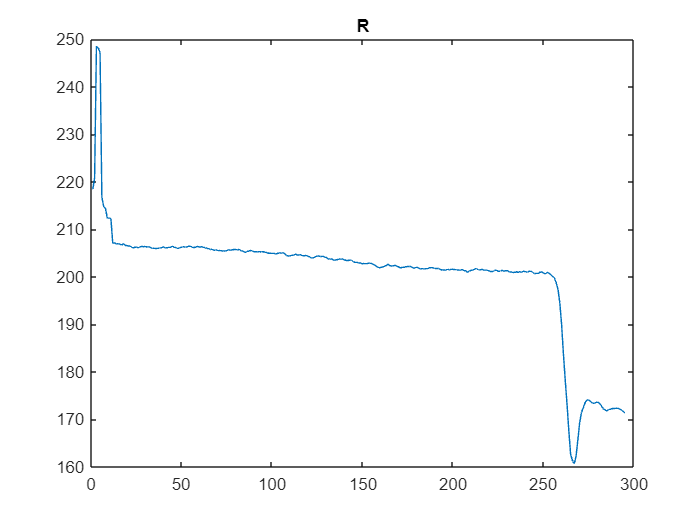

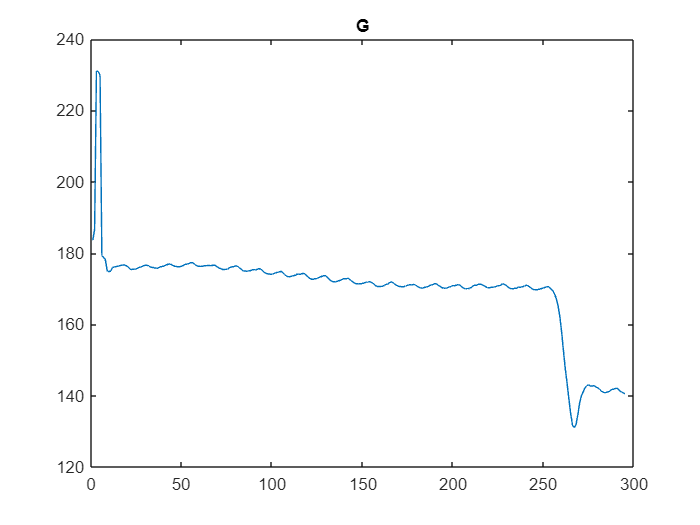

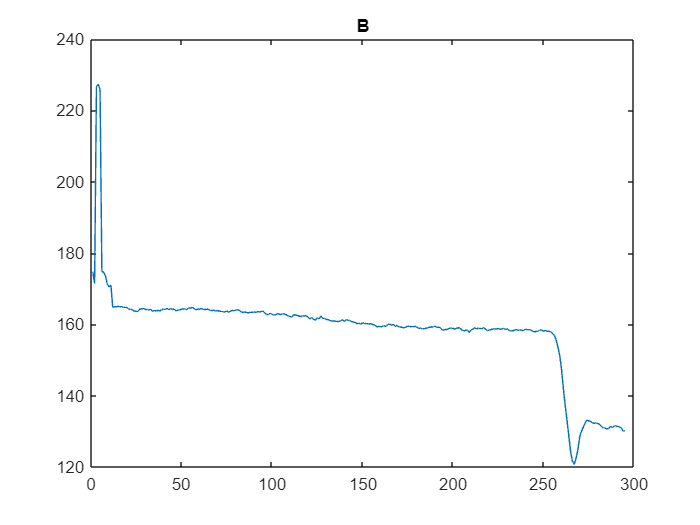

import1

Kod m-skryptu:

daneP = readmatrix('daneP.csv');

R = daneP(:, 1);

G = daneP(:, 2);

B = daneP(:, 3);

figure

subplot(1, 3, 1)

plot(R)

title("R")

subplot(1, 3, 2)

plot(G)

title("G")

subplot(1, 3, 3)

plot(B)

title("B")

### Zad b

Z zaimportowanych danych wybierz taki fragment, na którym widoczny jest sygnał okresowy. Utwórz nową zmienną zawierającą wybrany fragment sygnału i zwizualizuj ją na osobnym oknie wykresu. - Wskazówka: Przyglądnij się wykresowi każdej składowej i wybierz taką, na której okresowość jest najlepiej widoczna. Następnie, przy pomocy indeksowania, wybierz fragment pomijając zakłócenia na początku i na końcu sygnału.

okres = daneP(180:230,:)

okres =   202.0200  170.7400  159.1700
  201.8600  170.4400  158.8400
  201.6500  170.2600  158.9400
  201.7500  170.1400  158.7100
  201.6200  170.3100  158.7600
  201.7200  170.4500  158.8700
  201.7100  170.5700  159.0900
  201.9100  170.8800  159.1000
  201.9200  171.0500  159.3400
  201.8800  171.1600  159.1800


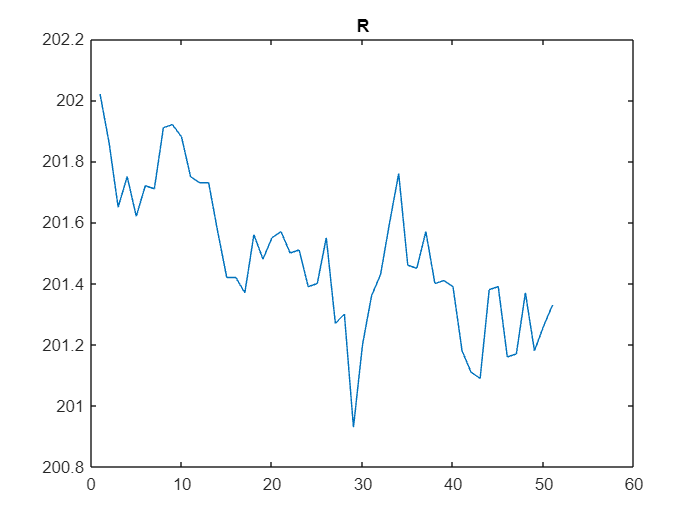

figure("Name","R")
plot(okres(:, 1))
title("R")

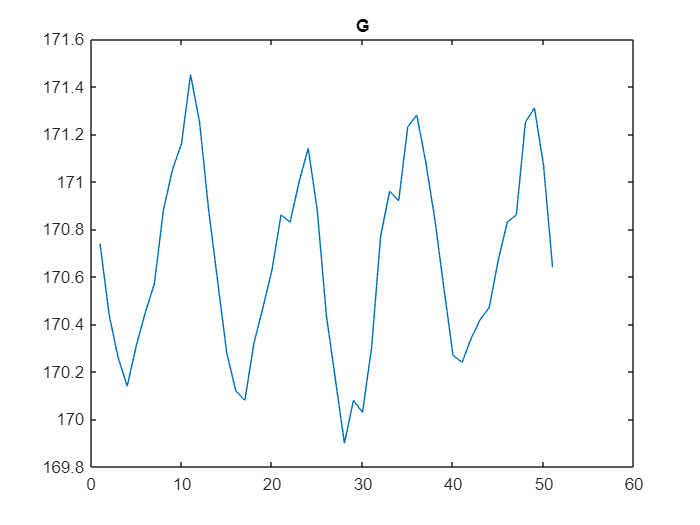

figure("Name","G")
plot(okres(:, 2))
title("G")

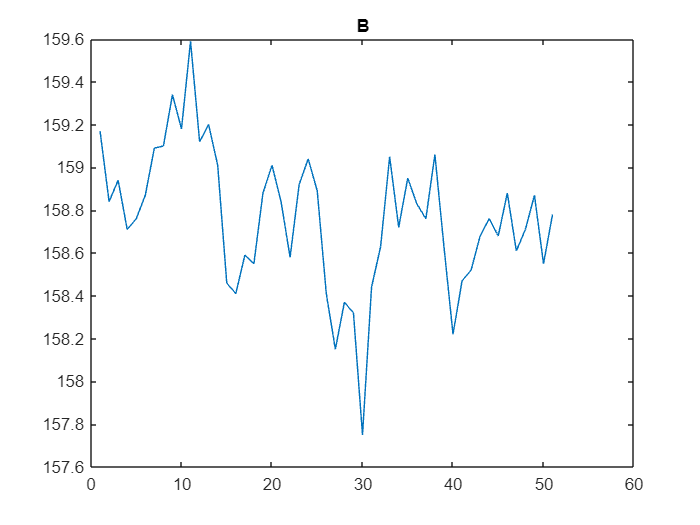

figure("Name","B")
plot(okres(:, 3))
title("B")

### Zad c

Z wybranego fragmentu sygnału, usuń trend poprzez dopasowanie krzywej wielomianowej. Dobierz stopień wielomianu jak najmniejszego stopnia przy zachowaniu jak najmniejszego błędu dopasowania (funkcja norm). Do wykresu z poprzedniego punktu dodaj linię dopasowanego trendu (inny kolor). Utwórz nowy wykres zawierający sygnał z usuniętym trendem. - Wskazówka – możesz zrealizować dopasowanie przy pomocy narzędzia Basic Fitting Tool, a następnie wygenerować m-kod i wybrać z niego potrzebne fragmenty analizy sygnału

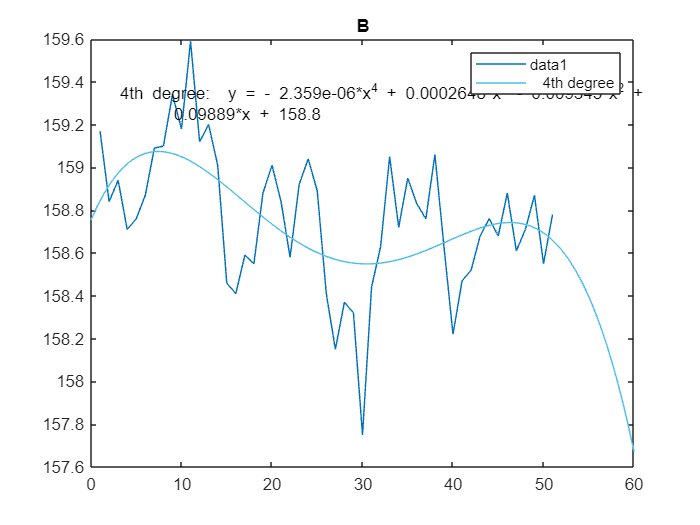

createfigure(okres(:, 3))

Zad d

Znajdź częstotliwość charakterystyczną sygnału. Sformatuj wykres dodając do niego w sposób programowy: opisy osi x,y i tytuł wykresu. Dodaj do wykresu punkt w miejscu maksimum (częstotliwość charakterystyczna) oraz opis informujący o wartości częstotliwości tego maksimum. - Wskazówka: użyj funkcji fft (patrz przykład w dokumentacji) z częstotliwością próbkowania odczytaną z pliku daneP.csv - Aby dodać do wykresu opis wykorzystaj funkcję text oraz sformatuj tekst przy pomocy funkcji sprintf.

Zad e

Uzupełnij m-plik o komentarze i dokumentacje. Wygeneruj raport w formacie HTML

## Zad 2

Zad a

Przy pomocy polecenia randn wygeneruj tablicę 3x3 liczb pseudolosowych R o rozkładzie normalnym (średnia 0 i odchylenie standardowe). Następnie utwórz zmienną A jako typ UINT32, zawierającą liczbę 100. Pomnóż zmienną R przez A, odpowiednio dostosowując typy danych. Rezultat (zmienna B) powinna być typu UINT32. Zwróć uwagę czy rezultaty mnożenia są poprawne ! W sprawozdaniu zanotuj liczbę bajtów potrzebną do zapamiętania jednej liczby typu double oraz jednej liczby typu UINT32 (wskazówka – skorzystaj z polecenie whos).

Zad b

Utwórz dwie tablice znakowe zawierające teksty: „ćwiczenie 2” oraz „laboratorium 1”. Połącz te dwie tablice tak aby tablica wynikowa zawierała tekst jak poniżej (wskazówka – skorzystaj z polecenia strvcat)

Zad c

Utwórz tablicę znakową str1 zawierającą tekst „Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud”. Znajdź indeksy słów zaczynających się na literę „b”, kończących na literę „d” i nie zawierających litery „u”. Wskazówka – skorzystaj z wyrażeń regularnych – dokumentacja do polecenia regexp

Zad d

Utwórz tablicę komórkową o rozmiarze 2x2 zawierającą następujące dane jak na rysunku poniżej. Wybierz z tablicy komórkowej, tablicę liczb pseudolosowych znajdującą się w komórce 2-wiersz, 1- kolumna, dodaj do niej wartość 100, a rezultat zapisz w to samo miejsce do tablicy komórkowej. 

Zad e

Oblicz całkę oznaczoną w przedziale 𝑥 ∈ (−2,2) z funkcji 𝑓(𝑥) = 𝑥 2 − 2 ∙ 𝑥 + 4 i narysuj jej wykres dla tego przedziału. Wskazówka – zdefiniuj funkcję przy pomocy uchwytu do funkcji, wykorzystaj funkcję quad oraz fplot.

Zad f

Utwórz typ danych tabelaryczny (table) zawierający dane jak na rysunku poniżej. Wyeksportuj dane z tabeli do pliku CSV. Wskazówka – sprawdź w systemie pomocy jak definiować nazwy kolumn oraz wierszy. Liczby do tabeli wygeneruj losowo. Skorzystaj z polecenia writetable